# **Proper Orthogonal Decomposition**

- Spatial POD

- Frequency Dependent POD

Velocity reconstruction for a single mode obtained from the application of Frequency Dependent POD

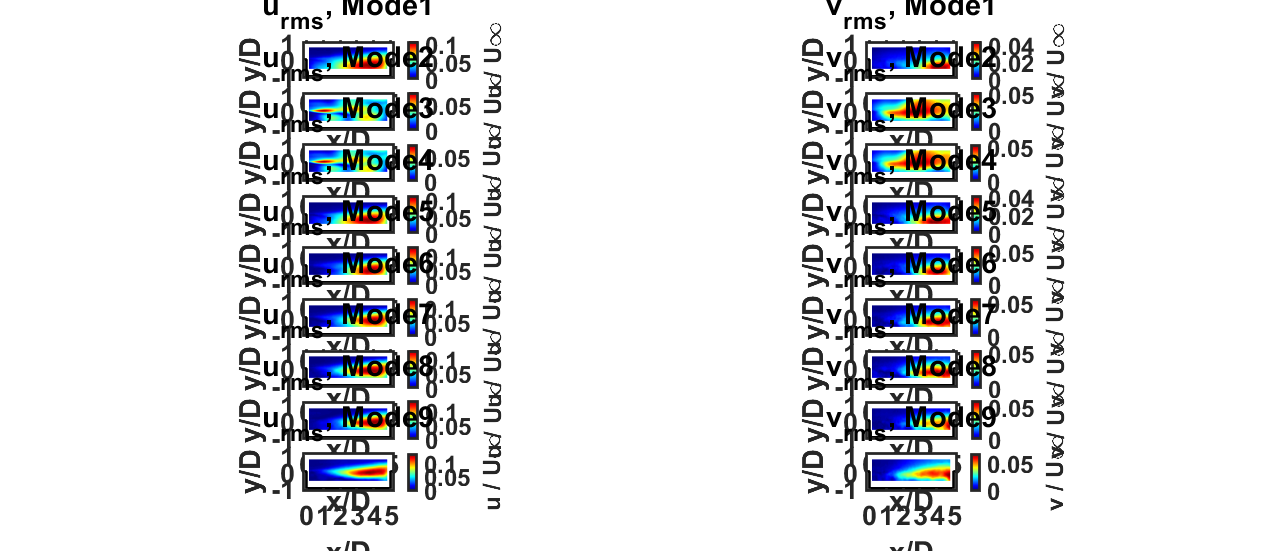

% Load Phi^l(x,f). It is Phi2 in the MATLAB variable space
load('Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\Phi2_280.mat');

% Load eigenvalue for getting Lambda_l,f and arrange it in decreasing energy fashion
% Extract l and f indices in decreasing energy fashion
eig1 = load('Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\eigval_280.txt');
[eigDec, m_index, f_index] = DecEn_eigval(eig1);

% Load u(x,f) for reconstruction
u_xt = load('Y:\rawdata\Sandia_cavity\Spectral velocity data\vel_ens\Mach0.8\ens_num_6.txt');
u_m = mean(u_xt,2);
u_xt = u_xt - u_m;
u_xf = fft(u_xt');

for ii = 1:9
% Select Phi(x) value for selected modal and frequency index in ii
Phi1 = Phi2(:,m_index(ii),f_index(ii));

% Extract a_l,f from u(x,f)
a_lf = u_xf*Phi1;

% Velocity Reconstruction
u_rec_f = Phi1*a_lf.';
u_rec_t1 = ifft(u_rec_f','symmetric');
u_rec_t = u_rec_t1';

% Rms 
u_rms = rms(u_rec_t,2);

% Contourplot of u_rms and v_rms
subplot(9,2,(2*ii)-1)
plot_cont_rms(u_rms, 1);
title(strcat('u_r_m_s, Mode ',int2str(ii)));

subplot(9,2,2*ii)
plot_cont_rms(u_rms,2);
title(strcat('v_r_m_s, Mode ',int2str(ii)));
end

Expansion coefficients can be extracted from the fluctuating flow field for Spatial POD. These expansion coefficients can be analyzed in frequency domain in terms of

% Load Phi value
clear all;
Phi = load('Y:\rawdata\Sandia_cavity\ConvergenceResults\Mach0.8\Phi_ensN_5000.txt');

% Load uv value for different ens_nums (1 to 280 here for example)
for ens_num = 1:280
    uv = load(strcat('Y:\rawdata\Sandia_cavity\Spectral velocity data\vel_ens\Mach0.8\ens_num_',int2str(ens_num),'.txt'));
    uv_m = mean(uv,2);
    uv = uv - uv_m;
    % Extract a_l,f
    a_lt(:,:) = Phi'*uv;
    a_lf(:,:,ens_num) = fft(a_lt');
end
save('Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\a_n\CrossCorrelation\a_lf.mat','a_lf_corr');

% Indicate frequency at which correlation calculated
for f_ind = 1:193
    a_lf1(:,:) = a_lf(f_ind,:,:);
    a_lf_corr(:,:,f_ind) = a_lf1*a_lf1';
end

% Save this correlation coefficient
save('Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\a_n\CrossCorrelation\a_lf_corr.mat','a_lf_corr');

These correlations can be plotted for rossiter frequencies, in the following code,

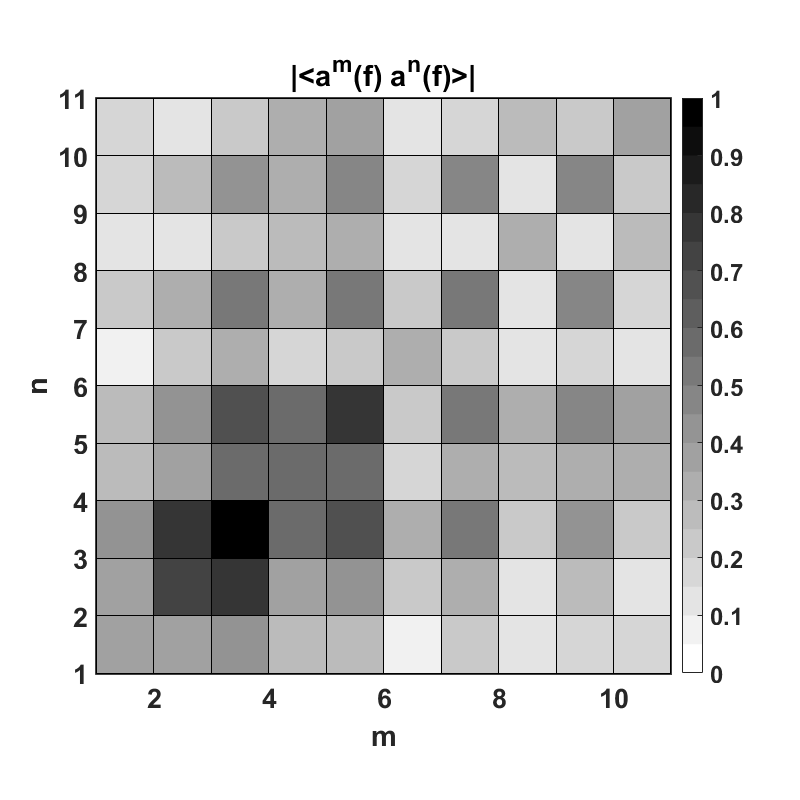

clear all;

% Load data containing correlation of expansion coefficients
load('Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\a_n\CrossCorrelation\a_lf_corr.mat');

% Indicate frequency index
f_ind = 7;
a_lf_corr1 = a_lf_corr(:,:,f_ind);

% Magnitude
a_lf_corr_mag = abs(a_lf_corr1);
a_lf_corr_mag_norm = a_lf_corr_mag/max(max(a_lf_corr_mag));
for ii = 1:11
    for jj = 1:11
        a_lf_corr_norm1(ii,jj) =  a_lf_corr_mag(ii,jj)/(sqrt(a_lf_corr_mag(ii))*sqrt(a_lf_corr_mag(jj)));
    end
end
% Angle
a_lf_corr_mag_phs = angle(a_lf_corr1);

figure();
c = gray(20);
c =  flipud(c);
colormap(c);
h = pcolor(a_lf_corr_mag_norm(1:11,1:11));
format_graph(1);
caxis([0 1])
colorbar;
ylabel('n','FontWeight','Bold','FontSize',38)
title('|<a^m(f) a^n(f)>|')
xlabel('m','FontWeight','Bold','FontSize',38), 

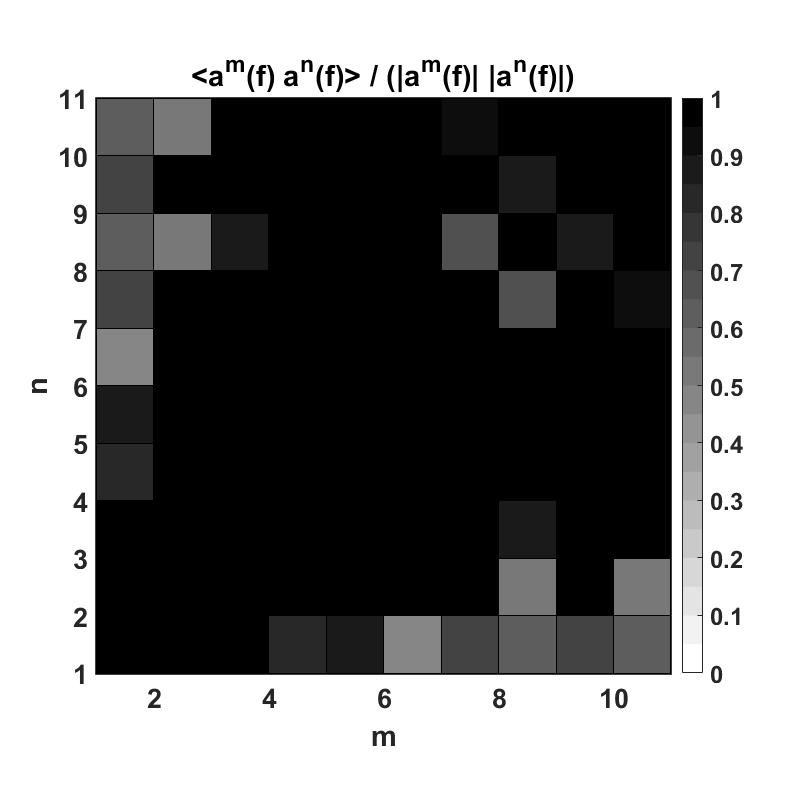

figure();
% Plot magnitudes
c = gray(20);
c = flipud(c);
colormap(c);
h = pcolor(a_lf_corr_norm1(1:11,1:11));
caxis([0 1]);
format_graph(1);
colorbar
title('<a^m(f) a^n(f)> / (|a^m(f)| |a^n(f)|)')
ylabel('n','FontWeight','Bold','FontSize',38)
xlabel('m','FontWeight','Bold','FontSize',38),

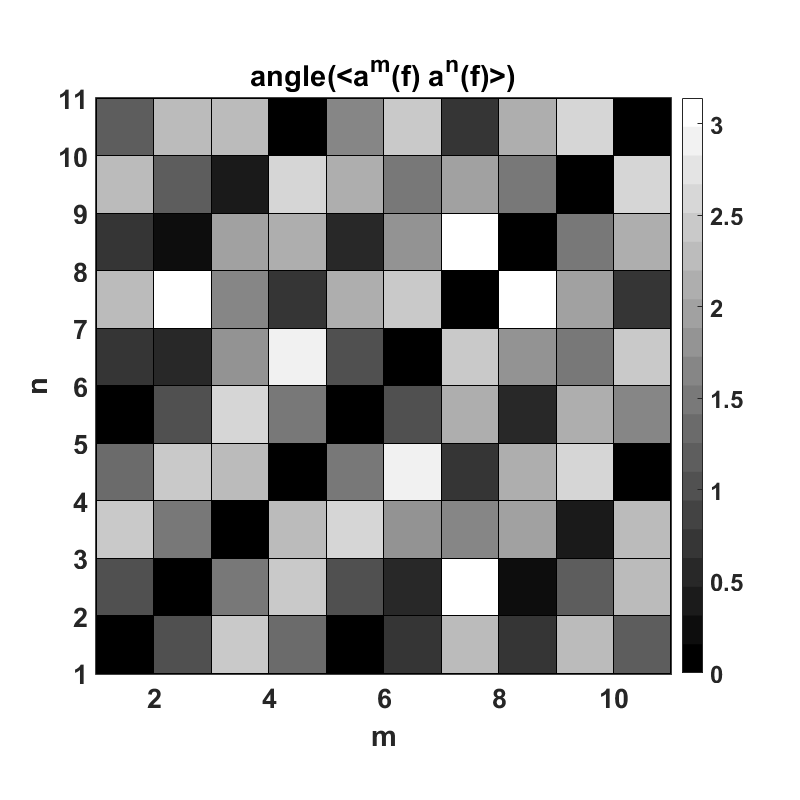

figure();
c = gray(20);
%c = flipud(c);
colormap(c);
h = pcolor(abs(a_lf_corr_mag_phs(1:11,1:11)));
caxis([0 3.14]);
format_graph(1);
ylabel('n','FontWeight','Bold','FontSize',38)
xlabel('m','FontWeight','Bold','FontSize',38),
title('angle(<a^m(f) a^n(f)>)')
colorbar;
pbaspect([1 1 1])

Frequency dependent POD expansion coefficients cross-correlations can be found from the following,

clear all;
load('Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\Phi3_280.mat');
for ens_num = 1:280
    uv = load(strcat('Y:\rawdata\Sandia_cavity\Spectral velocity data\vel_ens\Mach0.8\ens_num_',int2str(ens_num),'.txt'));
    uv_m = mean(uv,2);
    uv = uv - uv_m;
    u_xf = fft(uv');
    % Extract a_lf
    for f_ind = 1:193
        a_lf1(f_ind,:) = u_xf(f_ind,:)*Phi3(:,:,f_ind);
    end
    a_lf(:,:,ens_num) = a_lf1; 
end

% Get cross correlation 
for f_ind = 1:193
    a_lf2(:,:) = a_lf(f_ind,:,:);
    a_lf_corr(:,:,f_ind) = a_lf2*a_lf2';
end

% Save this correlation coefficient
save('Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\a_n\CrossCorrelation\a_lf_corr.mat','a_lf_corr');

clear all;

The correlation coefficients found from these can be found here,

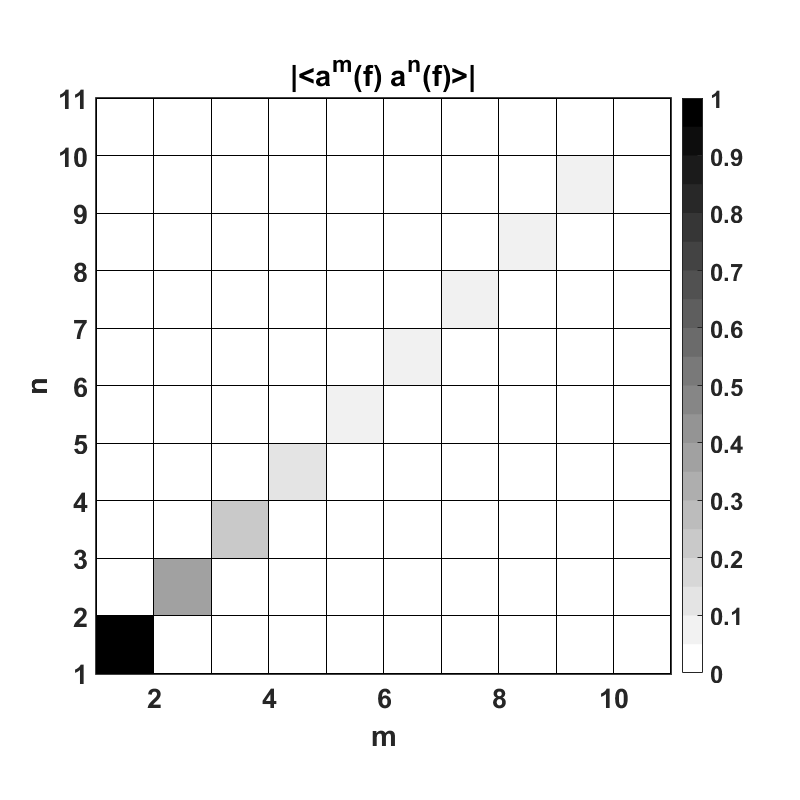

% load saved correlation matrix
load('Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\a_n\CrossCorrelation\a_lf_corr.mat');

%Indicate frequency at which the correlation matrix is calculated
f_ind = 25;
a_lf_corr1 = a_lf_corr(:,:,f_ind);

% Magnitude
a_lf_corr_mag = abs(a_lf_corr1);
a_lf_corr_mag_norm = a_lf_corr_mag/max(max(a_lf_corr_mag));


figure();
c = gray(20);
c =  flipud(c);
colormap(c);
h = pcolor(a_lf_corr_mag_norm(1:11,1:11));
format_graph(1);
caxis([0 1])
colorbar;
ylabel('n','FontWeight','Bold','FontSize',38)
title('|<a^m(f) a^n(f)>|')
xlabel('m','FontWeight','Bold','FontSize',38), 

Expansion coefficients from spatial POD

% Load Phi value
clear all;
Phi = load('Y:\rawdata\Sandia_cavity\ConvergenceResults\Mach0.8\Phi_ensN_5000.txt');

% Load uv value for different ens_nums (1 to 280 here for example)
for ens_num = 1:280
    uv = load(strcat('Y:\rawdata\Sandia_cavity\Spectral velocity data\vel_ens\Mach0.8\ens_num_',int2str(ens_num),'.txt'));
    uv_m = mean(uv,2);
    uv = uv - uv_m;
    % Extract a_l,f
    a_lt(:,:) = Phi'*uv;
    a_lf(:,:,ens_num) = fft(a_lt');
end
save('Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\a_n\CrossCorrelation\a_lf.mat','a_lf');

Expansion coefficients for frequency dependent POD,

clear all;
load('Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\Phi3_280.mat');
for ens_num = 1:280
    uv = load(strcat('Y:\rawdata\Sandia_cavity\Spectral velocity data\vel_ens\Mach0.8\ens_num_',int2str(ens_num),'.txt'));
    uv_m = mean(uv,2);
    uv = uv - uv_m;
    u_xf = fft(uv');
    % Extract a_lf
    for f_ind = 1:193
        a_lf1(f_ind,:) = u_xf(f_ind,:)*Phi3(:,:,f_ind);
    end
    a_lf(:,:,ens_num) = a_lf1; 
end
save('Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\a_n\CrossCorrelation\a_lf.mat','a_lf');

clear all;
load('Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\a_n\CrossCorrelation\a_lf.mat');
a_spat =  a_lf;
clear a_lf;
load('Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\a_n\CrossCorrelation\a_lf.mat');
a_fpod = a_lf;
clear a_lf;
af(:,:) = a_fpod(25,:,:);
as(:,:) = a_spat(25,1:15,:);
afs = af*as';
afs_den1 = sqrt(af*af');
afs_den2 = sqrt(as*as');
for ii = 1:15
    for jj = 1:15
        afss(ii,jj) = afs(ii,jj)/(afs_den1(ii,ii)*afs_den2(jj,jj));
    end
end
afs_mag = abs(afss);

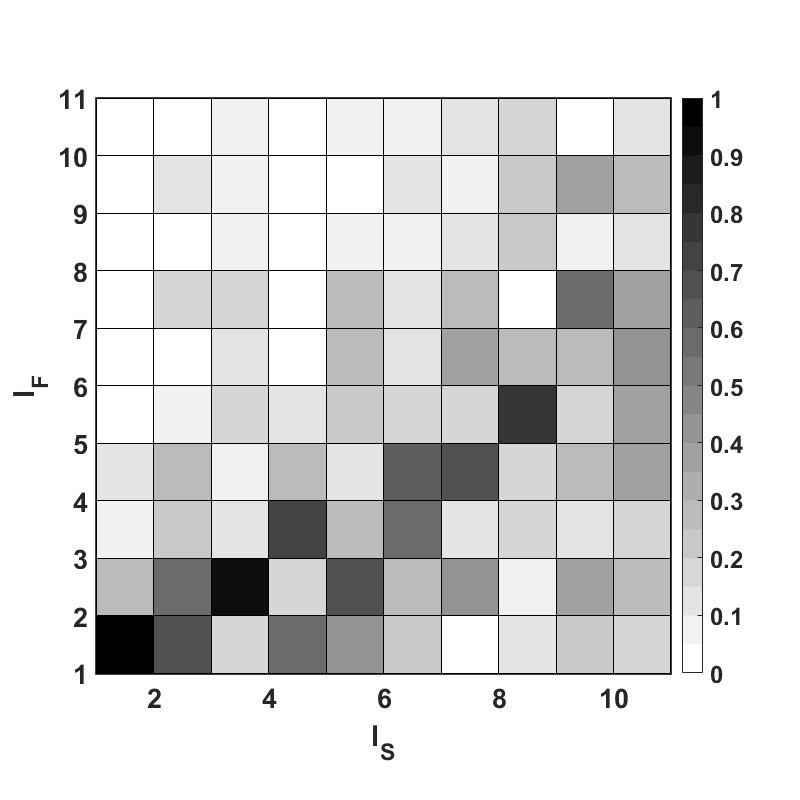

figure();
c = gray(20);
c =  flipud(c);
colormap(c);
h = pcolor(afs_mag(1:11,1:11));
format_graph(1);
caxis([0 1])
colorbar;
ylabel('l_F','FontWeight','Bold','FontSize',38)
xlabel('l_S','FontWeight','Bold','FontSize',38), 

The cross correlation between the velocity fields can be an important parameter to study,

clear all;
Nb = 280;
uvs12 = 0;
uvs11 = 0;
uvs22 = 0;
for ens_num = 1:Nb
    uv1 = load(strcat('Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\50PercentEnergy_7\uv_rec_',int2str(ens_num),'.txt'));
    uv2 = load(strcat('Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\DecreasingEnergy\50Energy_146modes\uv_rec_',int2str(ens_num),'.txt'));
    uv12 = uv1.*uv2;
    uvs12 = uvs12 + sum(sum(uv12));
    uvden1 = uv1.^2;
    uvden2 = uv2.^2;
    uvs11 = uvs11 + sum(sum(uvden1));
    uvs22 = uvs22 + sum(sum(uvden2));
end

%uv1 = load('Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\20PercentEnergy_1\uv_rec_6.txt');
%uv2 = load('Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\DecreasingEnergy\20Energy_9modes\uv_rec_6.txt');
uv_corr = uvs12/(sqrt(uvs11)*sqrt(uvs22));

clear all;
Nb = 280;
uvs12 = zeros(6360,1);
uvden1 = zeros(6360,1);
uvden2 = zeros(6360,1);
for ens_num = 1:Nb
    uv1 = load(strcat('Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\65PercentEnergy_16\uv_rec_',int2str(ens_num),'.txt'));
    uv2 = load(strcat('Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\DecreasingEnergy\65Energy_599modes\uv_rec_',int2str(ens_num),'.txt'));
    uv12 = uv1.*uv2;
    uv11 = uv1.^2;
    uv22 = uv2.^2;
    uvs12 = uvs12 + sum(uv12,2);
    uvden1 = uvden1 + sum(uv11,2);
    uvden2 = uvden2 + sum(uv22,2);
end
for ii = 1:6360
    uvcorr(ii,1)= uvs12(ii,1)/(sqrt(uvden1(ii,1))*sqrt(uvden2(ii,1)));
end
%save('Y:\rawdata\Sandia_cavity\Comparisons\uvcorrS65F65.txt','uvcorr','-ascii');
%save('Y:\rawdata\Sandia_cavity\Comparisons\uvS75S75.txt','uvden1','-ascii');
%save('Y:\rawdata\Sandia_cavity\Comparisons\uvF50F50.txt','uvden2','-ascii');

This section calculates correlation coefficient between FPOD and measured velocity datasets.

clear all;
Nb = 280;
uvs12 = zeros(6360,1);
uvden1 = zeros(6360,1);
uvden2 = zeros(6360,1);
for ens_num = 1:Nb
    uv1 = load(strcat('Y:\rawdata\Sandia_cavity\Spectral velocity data\vel_ens\Mach0.8\ens_num_',int2str(ens_num),'.txt'));
    uv1_m = mean(uv1,2);
    uv1 = uv1 - uv1_m;
    uv2 = load(strcat('Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\DecreasingEnergy\50Energy_146modes\uv_rec_',int2str(ens_num),'.txt'));
    uv12 = uv1.*uv2;
    uv11 = uv1.^2;
    uv22 = uv2.^2;
    uvs12 = uvs12 + sum(uv12,2);
    uvden1 = uvden1 + sum(uv11,2);
    uvden2 = uvden2 + sum(uv22,2);
end
for ii = 1:6360
    uvcorr(ii,1)= uvs12(ii,1)/(sqrt(uvden1(ii,1))*sqrt(uvden2(ii,1)));
end
%save('Y:\rawdata\Sandia_cavity\Comparisons\uvcorrF50M.txt','uvcorr','-ascii');
%save('Y:\rawdata\Sandia_cavity\Comparisons\uvMM.txt','uvden1','-ascii');
%save('Y:\rawdata\Sandia_cavity\Comparisons\uvF50F50.txt','uvden2','-ascii');

This section calculates correlation coefficient for spatial velocity reconstructions with measured velocity fields,

clear all;
Nb = 280;
uvs12 = zeros(6360,1);
uvden1 = zeros(6360,1);
uvden2 = zeros(6360,1);
for ens_num = 1:Nb
    uv1 = load(strcat('Y:\rawdata\Sandia_cavity\Denoise velocity data\vel_ens\Mach0.8\ens_num_',int2str(ens_num),'.txt'));
    uv1_m = mean(uv1,2);
    uv1 = uv1 - uv1_m;
    uv2 = load(strcat('Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\65PercentEnergy_16\uv_rec_',int2str(ens_num),'.txt'));
    uv12 = uv1.*uv2;
    uv11 = uv1.^2;
    uv22 = uv2.^2;
    uvs12 = uvs12 + sum(uv12,2);
    uvden1 = uvden1 + sum(uv11,2);
    uvden2 = uvden2 + sum(uv22,2);
end
for ii = 1:6360
    uvcorr(ii,1)= uvs12(ii,1)/(sqrt(uvden1(ii,1))*sqrt(uvden2(ii,1)));
end
%save('Y:\rawdata\Sandia_cavity\Comparisons\uvcorrS65M.txt','uvcorr','-ascii');
%save('Y:\rawdata\Sandia_cavity\Comparisons\uvDD.txt','uvden1','-ascii');
%save('Y:\rawdata\Sandia_cavity\Comparisons\uvF50F50.txt','uvden2','-ascii');

This section mostly deals with frequency content i.e. PSD plots for Rossiter modes

clear all;
[L,D,Ma,Uinf,Fs,N,Nb] = load_parameters(1);
for ens_num = 1:Nb
    uv_ens = load(strcat('Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\RossiterModes\RossiterMode3\uv_rec_',int2str(ens_num),'.txt'));
    uv_osd(:,:,ens_num) = pwr_sp_dnst(uv_ens',Fs);
end
%save('Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\RossiterModes\RossiterMode3\uv_osd.mat','uv_osd','-v7.3');

This section calculates PSD values of all the energies associated with Frequency Dependent POD

clear all;
[L,D,Ma,Uinf,Fs,N,Nb] = load_parameters(1);
for ens_num = 1:Nb
    uv_ens = load(strcat('Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\DecreasingEnergy\50Energy_146modes\uv_rec_',int2str(ens_num),'.txt'));
    uv_osd(:,:,ens_num) = pwr_sp_dnst(uv_ens',Fs);
end
save('Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\DecreasingEnergy\50Energy_146modes\uv_osd.mat','uv_osd','-v7.3');

This section is for PSD for Spatial POD,

clear all;
[L,D,Ma,Uinf,Fs,N,Nb] = load_parameters(1);
for ens_num = 1:Nb
    uv_ens = load(strcat('Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\65PercentEnergy_16\uv_rec_',int2str(ens_num),'.txt'));
    uv_osd(:,:,ens_num) = pwr_sp_dnst(uv_ens',Fs);
end
save('Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\65PercentEnergy_16\uv_osd.mat','uv_osd','-v7.3');

PSD value for measured

clear all;
[L,D,Ma,Uinf,Fs,N,Nb] = load_parameters(1);
for ens_num = 1:Nb
    uv_ens = load(strcat('Y:\rawdata\Sandia_cavity\Spectral velocity data\vel_ens\Mach0.8\ens_num_',int2str(ens_num),'.txt'));
    uv_ensm = mean(uv_ens,2);
    uv_ens = uv_ens - uv_ensm;
    uv_osd(:,:,ens_num) = pwr_sp_dnst(uv_ens',Fs);
end
save('Y:\rawdata\Sandia_cavity\Spectral velocity data\vel_ens\Mach0.8\uv_osd.mat','uv_osd','-v7.3');

clear all;
load('Y:\rawdata\Sandia_cavity\SpectralConvergenceResults_Mach0.6\Phi_260.mat');
%load('Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\Phi2_280.mat');
eval1 = load('Y:\rawdata\Sandia_cavity\SpectralConvergenceResults_Mach0.6\eigval_260.txt');
Phi_1 = Phi(:,:,15);
clear Phi;
load('Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\Phi3_280.mat');
Phic1 = Phi_1(:,1:11);
Phic2 = Phi3(:,1:11,15);
Phic = (Phic1')*(Phic2);
PhicA = abs(Phic);
figure();
c = gray(20);
c =  flipud(c);
colormap(c);
h = pcolor(PhicA(1:11,1:11));
format_graph(1);
caxis([0 1])
colorbar;
ylabel('Mach 0.6','FontWeight','Bold','FontSize',38)
xlabel('Mach 0.8','FontWeight','Bold','FontSize',38),

clear all;
load('Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\a_n\CrossCorrelation\a_lf.mat');
for ii = 1:280
    a_lf1(:,:,ii) = a_lf(:,:,ii).*conj(a_lf(:,:,ii));
end
a_lf2 = mean(a_lf1,3);
a_lf3 = a_lf2(1:193,:);
a_lf3 = a_lf3/sum(sum(a_lf3));

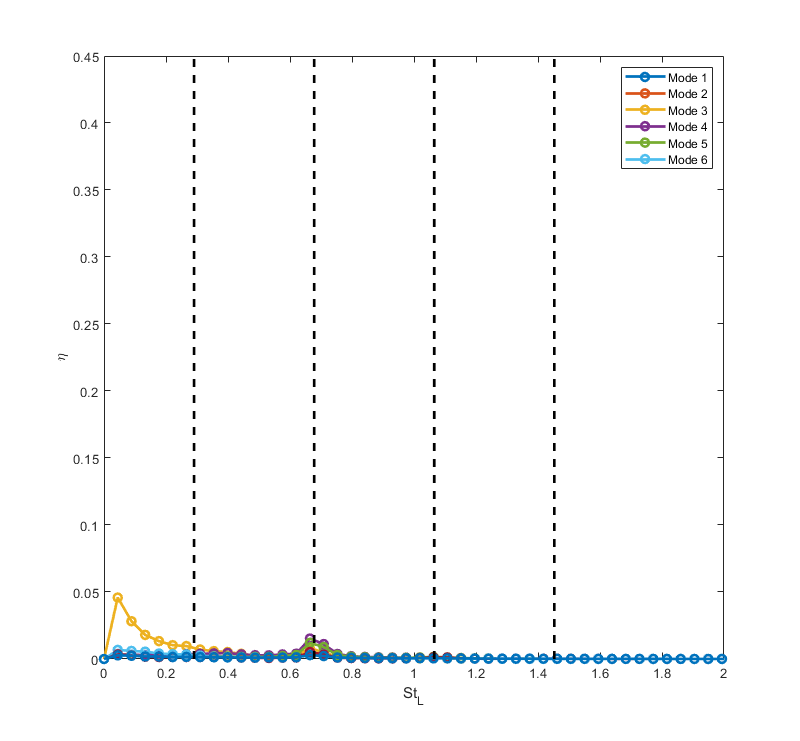

plot(0:18750/192*0.127/280:18750*0.127/280,a_lf3(:,1),'o-','LineWidth',2)
hold on
plot(0:18750/192*0.127/280:18750*0.127/280,a_lf3(:,2),'o-','LineWidth',2)
plot(0:18750/192*0.127/280:18750*0.127/280,a_lf3(:,3),'o-','LineWidth',2)
plot(0:18750/192*0.127/280:18750*0.127/280,a_lf3(:,4),'o-','LineWidth',2)
plot(0:18750/192*0.127/280:18750*0.127/280,a_lf3(:,5),'o-','LineWidth',2)
plot(0:18750/192*0.127/280:18750*0.127/280,a_lf3(:,6),'o-','LineWidth',2)
r_freq = Ros_freq(0.8,4,0.127);
St_ros = r_freq.*0.127/280;
plot([St_ros(1) St_ros(1)], [0 0.05], '--','LineWidth',2,'Color',[0 0 0])
plot([St_ros(2) St_ros(2)], [0 0.05], '--','LineWidth',2,'Color',[0 0 0])
plot([St_ros(3) St_ros(3)], [0 0.05], '--','LineWidth',2,'Color',[0 0 0])
plot([St_ros(4) St_ros(4)], [0 0.05], '--','LineWidth',2,'Color',[0 0 0])
xlim([0 2])
legend('Mode 1', 'Mode 2', 'Mode 3', 'Mode 4', 'Mode 5', 'Mode 6')
xlabel('St_L')
ylabel('\eta')